# Difference method for solving boundary value problems for elliptic type equations

## Taks 1

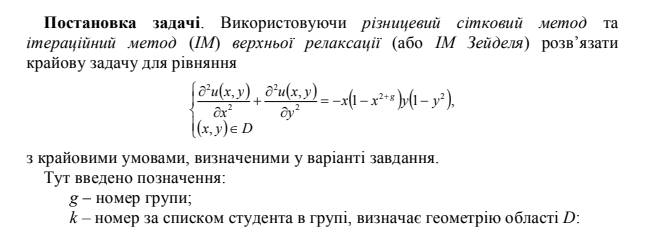

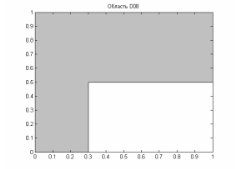

% параметри модельної задачі :
a=1; b=1;
Hx=0.005; Hy=0.01;

Nx=201; Ny=101;
Nx11=61; Ny11=61;

ro=1.965; e=1e-8; kmax=20000;
Nx1=Nx-1; Ny1=Ny-1;
X=0:Hx:a;
Y=0:Hy:b;
HxH=1./(Hx.*Hx); HyH=1./(Hy.*Hy);
C=ro.*0.5./(HxH+HyH); A=HxH.*C; B=HyH.*C; D=ro-1;

% формування крайових умов та початкового наближення :
U=zeros(Ny,Nx);
% (0 <= X < 0.3) & (0= Y)
for i=1:Nx11
    U(1,i)=lr7_mx11(X(i));
end

% (0 <= X < 0.3) & (1 = Y)
for i=1:Nx11
    U(Ny,i)=lr7_mx12(X(i));
end

% (0.3 <= X <= a) & (0.5 = Y)
for i=Nx11:Nx
    U(Ny11,i)=lr7_mx21(X(i));
end

% (0.3 <= X <= a) & (1 = Y)
for i=Nx11:Nx
    U(Ny1,i)=lr7_mx22(X(i));
end

k=0;
Fla=0;
while ~Fla && k<kmax
    Fla=1;
    k=k+1;
    for j=2:Ny11-1
        i=Nx11;
        u=U(j,i);
        UU=A.*2.0.*(U(j,i+1)-Hx.*lr7_my11(Y(j)))+...
        B.*(U(j-1,i)+U(j+1,i))-D.*u+C.*lr7_f(X(i),Y(j));
        if Fla
            Fla=abs(UU-u)<e;
        end

        U(j,i)=UU;
        i=1;
        u=U(j,i);
        UU=A.*2.0.*(U(j,i+1)-Hx.*lr7_my21(Y(j)))+B*(U(j-1,i)+U(j+1,i))-...
        D.*u+C.*lr7_f(X(i),Y(j));
        if Fla
            Fla=abs(UU-u)<e;
        end

        U(j,i)=UU;
        for i=2:Nx11-1
            u=U(j,i);
            UU=A.*(U(j,i-1)+U(j,i+1))+B.*(U(j-1,i)+U(j+1,i))-...
            D.*u+C.*lr7_f(X(i),Y(j));
            if Fla
                Fla=abs(UU-u)<e;
            end
            U(j,i)=UU;
        end
    end
    j=Ny11;
    for i=2:Nx11-1
        u=U(j,i);
        UU=A.*(U(j,i-1)+U(j,i+1))+B.*(U(j-1,i)+U(j+1,i))-...
        D.*u+C.*lr7_f(X(i),Y(j));
        if Fla
            Fla=abs(UU-u)<e;
        end
        U(j,i)=UU;
    end

    for j=Ny1+1:Ny-1
        i=Nx11;
        u=U(j,i);
        UU=A.*2.0.*(U(j,i+1)-Hx.*lr7_my12(Y(j)))+...
        B.*(U(j-1,i)+U(j+1,i))-D.*u+C.*lr7_f(X(i),Y(j));
        if Fla
            Fla=abs(UU-u)<e;
        end

        U(j,i)=UU;
        i=1;
        u=U(j,i);
        UU=A.*2.0.*(U(j,i+1)-Hx.*lr7_my21(Y(j)))+B*(U(j-1,i)+U(j+1,i))-...
        D.*u+C.*lr7_f(X(i),Y(j));
        if Fla
            Fla=abs(UU-u)<e;
        end
        U(j,i)=UU;

        for i=2:Nx11-1
            u=U(j,i);
            UU=A.*(U(j,i-1)+U(j,i+1))+B.*(U(j-1,i)+U(j+1,i))-...
            D.*u+C.*lr7_f(X(i),Y(j));
            if Fla
                Fla=abs(UU-u)<e;
            end
            U(j,i)=UU;
        end
    end
    j=Ny1;

    for i=2:Nx11-1
        u=U(j,i);
        UU=A.*(U(j,i-1)+U(j,i+1))+B.*(U(j-1,i)+U(j+1,i))-...
        D.*u+C.*lr7_f(X(i),Y(j));
        if Fla
            Fla=abs(UU-u)<e;
        end
        U(j,i)=UU;
    end

    for j=Ny11+1:Ny1-1
        i=Nx-1;
        u=U(j,i);
        UU=A.*2.0.*(U(j,i+1)-Hx.*lr7_my12(Y(j)))+B*(U(j-1,i)+U(j+1,i))-...
        D.*u+C.*lr7_f(X(i),Y(j));
        if Fla
            Fla=abs(UU-u)<e;
        end

        U(j,i)=UU;
        i=1;
        u=U(j,i);
        UU=A.*2.0.*(U(j,i+1)-Hx.*lr7_my21(Y(j)))+B*(U(j-1,i)+U(j+1,i))-...
        D.*u+C.*lr7_f(X(i),Y(j));
        if Fla
            Fla=abs(UU-u)<e;
        end

        U(j,i)=UU;

        for i=2:Nx-1
            u=U(j,i);
            UU=A.*(U(j,i-1)+U(j,i+1))+B*(U(j-1,i)+U(j+1,i))-...
            D.*u+C.*lr7_f(X(i),Y(j));
            if Fla
                Fla=abs(UU-u)<e;
            end
            U(j,i)=UU;
        end
    end
end
% побудова графіку розв'язку :
k

k = 20000

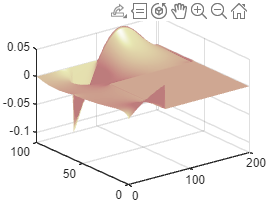

surfl(U);
shading interp;
colormap(pink);

function f=lr7_f(x,y)
    % Функція f(x,y)
    f=-x.*(1-x.^3).*y.*(1-y.^2);
end

function u=lr7_mx11(x)
    % Крайові умови на (0 <= X < 0.3) & (0 = Y)
    u=0.21.*x.*(1-x);
end

function u=lr7_mx12(x)
    % Крайові умови на (0 <= X < 0.3) & (1 = Y)
    u=0;
end

function u=lr7_mx21(x)
    % Крайові умови на (0.3 <= X <= a) & (0.5 = Y)
    u=0;
end

function u=lr7_mx22(x)
    % Крайові умови на (0.3 <= X <= a) & (1 = Y)
    xx=2.*x;
    u=xx.*(1-x).^2.*(xx-1);
end

function u=lr7_my11(y)
    % Крайові умови на (0<y<0.5)&(x=0.5)
    u=0.4.*y.*(1-y);
end

function u=lr7_my12(y)
    % Крайові умови на (0.5<y<1)&(x=1)
    u=y.*(1-y);
end

function u=lr7_my21(y)
    % Крайові умови на (0<y<1)&(x=0)
    u=0;
end